% there may be slight difference from paper (in term of number of samples) becase exact parameter values
% were not saved -- fig 2


load('chirp_signal.mat', 'fd', 'td');
disp('Loaded existing signal vector from generated_signal.mat');

Loaded existing signal vector from generated_signal.mat



Fm = 100;
BW = 2*pi*Fm;
c1 = 1;
alpha = 0.7069;
kappa = 1805;
shift = 1.2*c1;

[tn, time_stamps, f_n, loc, NoF] = ...
    sampling_running_func(fd, td, alpha, kappa, Fm, c1, shift);

% Interpolate signal values at the sample times
sample_values = interp1(td, fd, tn, 'linear');
disp(length(sample_values));

    53



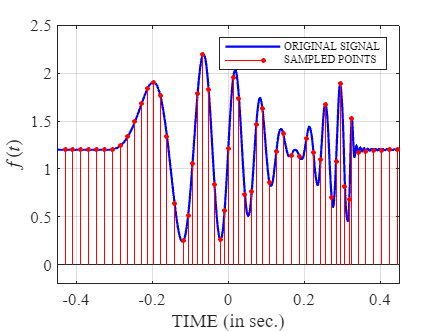

figure('Color','w');

% Original signal
plot(td, fd+shift, 'b', 'LineWidth', 1.2);
hold on;

% Sampled points
h = stem(tn, sample_values + shift, 'r');
h.Marker = '.';
h.MarkerSize = 8;
h.LineWidth = 0.5;

xlim([-0.45 0.45]);
ylim([-0.2 2.5]);

grid on;
box on;

xlabel('TIME (in sec.)','FontName','Times New Roman');
ylabel('$f(t)$','Interpreter','latex');

legend('ORIGINAL SIGNAL','SAMPLED POINTS', ...
       'Location','northeast', ...
       'FontSize', 6);

set(gca,'FontName','Times New Roman');